disp('Metoda bisekcji')

Metoda bisekcji



% funkcja
f = @(x) 2 * exp(-((x/3-1).^2)).^2 + 5*sqrt(x) - 8;

% Funkcja bisekcji
function [tableResults, errors, num_iter] = bisection(f, x_span, delta, x_ref)
    x_min = x_span(1);
    x_max = x_span(2);
    i = 0;
    iter = [];
    errors = [];

    while (x_max - x_min) / 2 > delta
        i = i + 1;  
        x_average = (x_min + x_max) / 2;
        iter = [iter; i, x_average, f(x_average)];

        if sign(f(x_average)) == sign(f(x_min))
            x_min = x_average;
        else
            x_max = x_average;
        end
    end

    x_final = (x_min + x_max) / 2;
    iter = [iter; i+1, x_final, f(x_final)];
    errors = abs(iter(:, 2) - x_ref);  % Błąd bezwzględny względem x_ref
    tableResults = array2table(iter, 'VariableNames', {'Iteration', 'x', 'f(x)'});
    num_iter = i + 1;
end

% Obliczenie miejsca zerowego za pomocą fzero jako punkt odniesienia
x_span = [1, 10];
x_ref = fzero(f, x_span);  % <- Punkt odniesienia
disp(['Miejsce zerowe obliczone za pomocą fzero: ', num2str(x_ref)]);

Miejsce zerowe obliczone za pomocą fzero: 1.7397



% Przykład użycia funkcji bisection i wyświetlenie wyników
delta = 10^-10; % Przykładowa wartość delta

[tableResults_bisection, errors_bisection, num_iter_bisection] = bisection(f, x_span, delta, x_ref);  % <- Wywołanie z x_ref
disp(tableResults_bisection);

    Iteration      x          f(x)    
    _________    ______    ___________

        1           5.5         4.2247
        2          3.25         2.9863
        3         2.125        0.97579
        4        1.5625       -0.48642
        5        1.8438        0.27519
        6        1.7031      -0.098514
        7        1.7734       0.090168
        8        1.7383     -0.0037228
        9        1.7559       0.043336
       10        1.7471       0.019835
       11        1.7427       0.008063
       12        1.7405      0.0021719
       13        1.7394    -0.00077505
       14        1.7399     0.00069851
       15        1.7397    -3.8239e-05
       16        1.7398     0.00033014
       17        1.7397     0.00014595
       18        1.7397     5.3858e-05
       19        1.7397     7.8093e-06
       20        1.7397    -1.5215e-05
       21        1.7397    -3.7028e-06


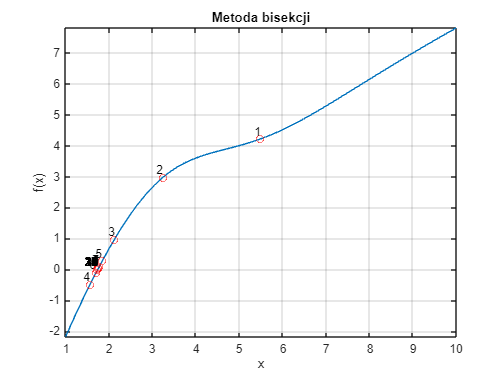


% Zapisanie tabeli wyników jako obrazek
fig = figure;
uitable('Data', tableResults_bisection{:,:}, 'ColumnName', tableResults_bisection.Properties.VariableNames, 'RowName', [], 'Units', 'Normalized', 'Position',[0, 0, 1, 1]);
set(fig, 'Name', 'Wyniki Metody Bisekcji', 'NumberTitle', 'off');
% Otworzenie w osobnym oknie
figure(fig);

% Rysowanie wykresu metody bisekcji
figure;
fplot(f, x_span);
xlabel('x');
ylabel('f(x)');
title('Metoda bisekcji');
grid on;
axis tight; % Automatyczne dopasowanie osi
hold on;
for i = 1:height(tableResults_bisection)
    plot(tableResults_bisection.x(i), tableResults_bisection.('f(x)')(i), 'ro');
    text(tableResults_bisection.x(i), tableResults_bisection.('f(x)')(i), num2str(i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
hold off;

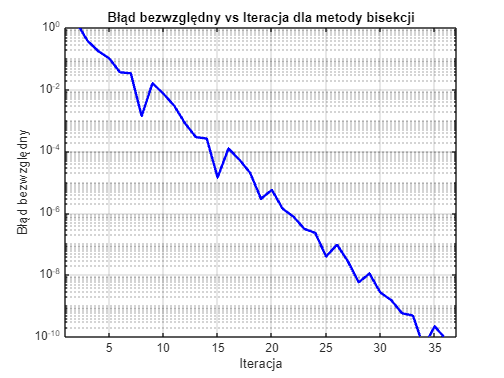


% Rysowanie wykresu błędów bezwzględnych dla metody bisekcji
figure;
semilogy(1:length(errors_bisection), errors_bisection, 'b-', 'LineWidth', 2);
xlabel('Iteracja');
ylabel('Błąd bezwzględny');
title('Błąd bezwzględny vs Iteracja dla metody bisekcji');
grid on;
xlim([1, length(errors_bisection)]); % Ustawienie zakresu osi X
ylim([10^-10, 1]); % Ustawienie zakresu osi Y
hold off;


% Zakres wartości delta
deltas = logspace(-15, -1, 15);

% Wyznaczenie liczby iteracji dla różnych wartości delta
num_iterations_bisection = zeros(length(deltas), 1);
for j = 1:length(deltas)
    delta = deltas(j);
    [~, ~, num_iter] = bisection(f, x_span, delta, x_ref);
    num_iterations_bisection(j) = num_iter;
end

% Wyświetlenie wyników w tabeli
iterations_table_bisection = table(deltas', num_iterations_bisection, 'VariableNames', {'Delta', 'Bisection iteration'});
disp(iterations_table_bisection);

    Delta     Bisection iteration
    ______    ___________________

     1e-15            53         
     1e-14            50         
     1e-13            47         
     1e-12            44         
     1e-11            40         
     1e-10            37         
     1e-09            34         
     1e-08            30         
     1e-07            27         
     1e-06            24         
     1e-05            20         
    0.0001            17         
     0.001            14         
      0.01            10         
       0.1             7         



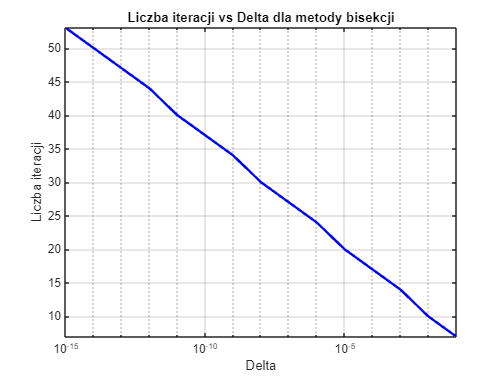


% Rysowanie wykresu liczby iteracji w zależności od delta dla metody bisekcji
figure;
semilogx(deltas, num_iterations_bisection, 'b-', 'LineWidth', 2);
xlabel('Delta');
ylabel('Liczba iteracji');
title('Liczba iteracji vs Delta dla metody bisekcji');
grid on;
axis tight; % Automatyczne dopasowanie osi
hold off;